# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.File = mfilename;
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Data_new'];                               
Deci.SubjectList        = 'all';
Deci.Step               =1; % Define Trial;
Deci.Proceed            =1;                          % If 0 or 1, Do you want Deci to automatically proceed to next steps? Suggest 0 for first-time users.
Deci.Layout.Noeye       = 'Collab_noeye.mat';         % Layout without Ocular Channels, Default is ReinhartLab 1020 system
Deci.Layout.eye         = 'Collab_eye.mat';           % Layout with Ocular Channels
Deci.PCom               = 0;        % Activates Parallel Computing (if availible)
Deci.Debug              = 0;        % Activates dbstop if error
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\ProcessedData'];     

Deci = Checkor(Deci);

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {300};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {400};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[10] [11]};   
    Deci.DT.Locks      = [10 11];     
    Deci.DT.Conditions = [1 2];         
    Deci.DT.Toi        = [-2 2]; 

if Deci.Step <= 1
    DefineTrialor(Deci);
    if ~Deci.Proceed; return; end
end

evaluating trialfunction 'expfunor'


## 2. PreProcessing Steps

####    Rereference channel to average of Implicit Electrode and Offline Reference

   Deci.PP.Imp                = 'RM:LM'; % 'Impicit Reference?[Implicit:RefChannels without Implicit]'
   Deci.PP.Ocu                = '';    % 'Ocular Reref?[Ref-Channels without Ref]'

#### Other Processing Steps

    Deci.PP.ScalingFactor       = [];               % Scalar, If the data needs to scale
    Deci.PP.HBP                 = [];               % Scalar,High-bandpass filter, in Hz.
    Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.
    
    Deci.PP.Repair              = [];                           % Structure, View and Repair (via interpoltation) Channels
%     Deci.PP.Repair.Type         = 'Manual';                   % String,'Manual' or 'Auto'
%     Deci.PP.Repair.Auto         = {};                         % Nx1 Subject cell array of Mx1 cells of M Channels to reject.

    Deci.PP.CleanLabels = 0; % Binary, normalize electrode names to be compatiable with Reinhart Lab's Needs.

if Deci.Step <= 2
    PreProcessor(Deci)
    if ~Deci.Proceed; return; end
end

## 3. Artifact Rejection

#### Individual Component Analysis

    Deci.Art.ICA.Reject                     = 0; % Whether or Not to do ICA
    Deci.Art.ICA.Eye.Chans           = {'VEM' , 'HEM'}; 

#### Trial Artifacts

     Deci.Art.TR.Toi              = [-.5 -.2];          % Time Range of Interest to look for Artifacts
 
     Deci.Art.TR.Eye                  = [];               % Comment the rest of .Eye to not do Eye Artifact Trial Rejection
%      Deci.Art.TR.Eye.Interactive      =  0;                % Enable Interactive Trial Artifact Rejection
%      Deci.Art.TR.Eye.Chans            = {'BVEOG','RHEOG','AF7','AF8'};    % 1xChan Cell Array of Ocular Eye Channels

    Deci.Art.TR.Muscle               = [];               % Comment the rest of .Muscle to not do Muscle Artifact Trial Rejection
%     Deci.Art.TR.Muscle.Interactive   = 0;                % Enable Interactive Trial Artifact Rejection

#### Manual Visual Artifact Rejection

    Deci.Art.Manual = [];
%     Deci.Art.Manual.Toi              = [-.5 -.2];

if Deci.Step <= 3
    Artifactor(Deci);
    if ~Deci.Proceed; return; end
end

## 4. Analysis

#### General Set-Up

    Deci.Analysis.ArtifactReject     =0;                    % Specify whether or not to Apply Trial Rejection
    Deci.Analysis.Channels           = {'Fz','Cz','C3','O1'};                % Cell array of channels or 'all'

#### Time-Frequency Analysis

    Deci.Analysis.Freq               = [];           % Comment the rest of .Freq to not do Fourier Transformation
    Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
    Deci.Analysis.Freq.foi           = exp(linspace(log(2),log(40),40));       % Frequency of Interest
    Deci.Analysis.Freq.width         = 7 ;           % Width
    Deci.Analysis.Freq.gwidth        = 4;            % Gwidth
    Deci.Analysis.Freq.Toi           = [-.5 1];       % Time Range

#### Cross-Frequency Coupling 

            Requires* .Freq * to have been done.

    Deci.Analysis.Freq.CFC = [];
    Deci.Analysis.Freq.CFC.chanlow = {'Fz' 'Cz'};
    Deci.Analysis.Freq.CFC.chanhigh = {'C3' 'O1'}; %Try not to do all to all if you have more than 10 chans
    
    Deci.Analysis.Freq.CFC.latencyhigh = [-.5 .5]; %no implementation yet to check for edge artifactsm so be careful
    Deci.Analysis.Freq.CFC.latencylow = [-.5 .5];
    
    Deci.Analysis.Freq.CFC.Freqhigh = 'beta';
    Deci.Analysis.Freq.CFC.Freqlow = 'theta';
    
    Deci.Analysis.Freq.CFC.timebin = 5;
    Deci.Analysis.Freq.CFC.methods = {'mi','plv'};  
    Deci.Analysis.Freq.CFC.keeptrials =  'no';

if Deci.Step <= 4
    Analyzor(Deci)
    if ~Deci.Proceed; return; end
end

## 5. Plotting

#### General Set-Up

    Deci.Plot.GA =  1;                       % 0 for Individual Plots, 1 for GrandAverage
    Deci.Plot.Scale = 'linear';
    Deci.Plot.Save = [];
    Deci.Plot.Save.Format =  'fig';

#### Math

    Deci.Plot.Math = [];
    Deci.Plot.Math.Form = {'[x1+x3]','[x2+x4]','x6-x5'};    % in this example sum of Cond1 and Cond3 makes Cond 5,                
    Deci.Plot.Math.Type = 0;                    % 0 = no math plots, 1 = only math plots, 2 = both math and single plots
    

#### Time-Frequency

    Deci.Plot.Freq = [];
    
    
    Deci.Plot.Freq.Plot = 0;                % 1 or 0 to do Freq Plots
    Deci.Plot.Freq.Foi = [3 4.5]; 
    Deci.Plot.Toi = [0 .8];
    Deci.Plot.Freq.Channel = [{'VEM'  'HEM'  'F3'  'F4'  'C3'  'C4'  'P3'  'P4'  'PO3'  'PO4'  'O1'  'O2'  'OL'  'OR'  'T3'  'T4' 'T5'  'T6'  'Fz'  'Cz'  'Pz'  'LM' 'RM'}];   
    Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'
     
    Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
    Deci.Plot.Freq.Roi = [];          % use 'maxmin','maxabs or [min max] to set.
    Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

    Deci.Plot.Freq.Topo = 1;
    Deci.Plot.Freq.Square = 1;
    
    Deci.Plot.PRP = [];
    Deci.Plot.ERP = [];
    Deci.Plot.Freq.Wires = [];
    

####     Cross-Frequency Coupling

    Deci.Plot.CFC = []; 
    Deci.Plot.CFC.method = 'plv';
    Deci.Plot.CFC.Topo = 1;
    Deci.Plot.CFC.Square = 1;
    Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest
    

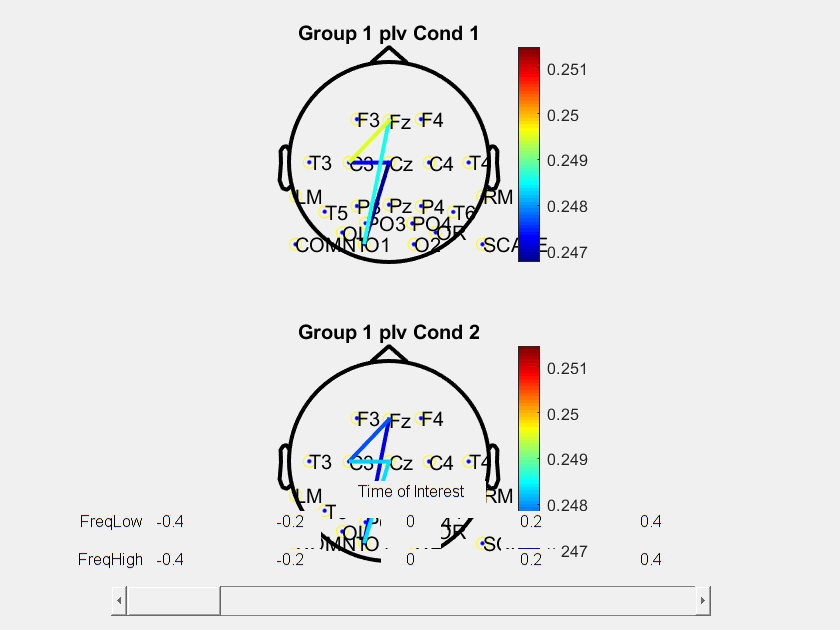

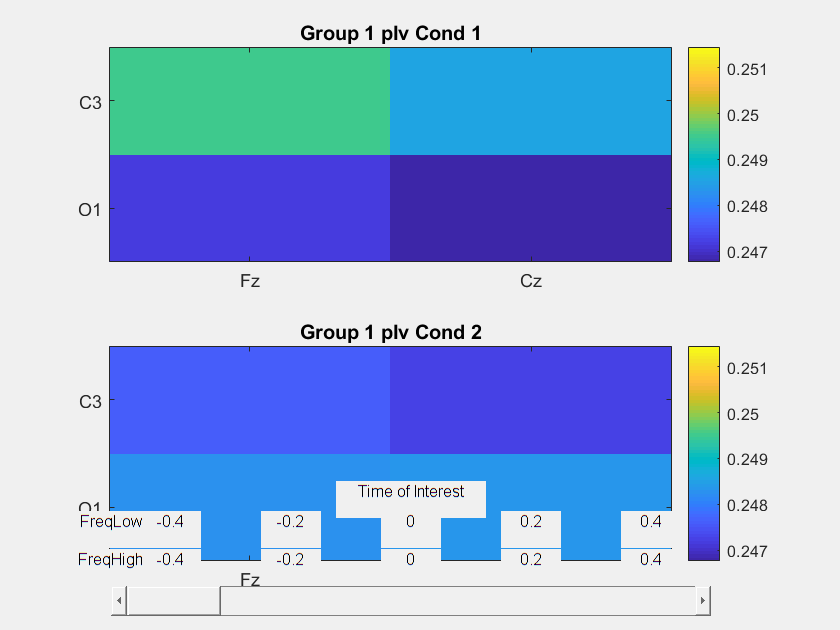

reading layout from file Collab_noeye.mat
the call to "ft_prepare_layout" took 0 seconds


plotting connections...
plotting connection 1 from 4 (Fz -> C3)

the call to "ft_topoplotCC" took 0 seconds
reading layout from file Collab_noeye.mat
the call to "ft_prepare_layout" took 0 seconds


plotting connections...
plotting connection 4 from 4 (Cz -> O1)

the call to "ft_topoplotCC" took 0 seconds


if Deci.Step <= 5
    Plottor(Deci);
    if ~Deci.Proceed; return; end
end